Eigenvalues

A=[4 -5;2 -3];
syms lambda; B=A - lambda*eye(size(A));
S=solve(det(B),lambda)

$$S = \left(\begin{array}{c} -1\\ 2 \end{array}\right)$$

Compute eigenvalues 1

A=[4 -5;2 -3];
[V, D]=eig(A)
%Othwerise
[V,d]=eig(A,'vector');

Compute eigenvalues with symbolic ( the column of V are the bases that span the eigenspace)

A=sym([4 -5;2 -3]);
[V, D]=eig(A)

$$V = \left(\begin{array}{cc} 1 & \frac{5}{2}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} -1 & 0\\ 0 & 2 \end{array}\right)$$

V1=null(A-D(1,1)*eye(size(A)))

$$V1 = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

V2=null(A-D(2,2)*eye(size(A)))

$$V2 = \left(\begin{array}{c} \frac{5}{2}\\ 1 \end{array}\right)$$

disp(rank([V1 V(:,2)]))

     2



disp(rank([V2 V(:,1)]))

     2



Compute eigenvalues with symbolic  part 2

A=[3 -2 0;-2 3 0; 0 0 5]; %Define Matrix
[V, D]=eig(sym(A)) %Compute eigenvectors

$$V = \left(\begin{array}{ccc} 1 & -1 & 0\\ 1 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 5 & 0\\ 0 & 0 & 5 \end{array}\right)$$


d=roots(charpoly(A)); %Compute eigenvalues as roots of the char. polynomial of A
syms lambda
B=A-lambda*eye(size(A)); %B= A - lambda *IdentityMatrix

%Substitute eigenvalues from D main diagonal into V
V1=null(subs(B,lambda,D(1,1))) 

$$V1 = \left(\begin{array}{c} 1\\ 1\\ 0 \end{array}\right)$$

V2=null(subs(B,lambda,D(2,2)))

$$V2 = \left(\begin{array}{cc} -1 & 0\\ 1 & 0\\ 0 & 1 \end{array}\right)$$

clf;
subspace(V1,V2) %Compute angle between two subspaces.

$$ans = \frac{\pi }{2}$$

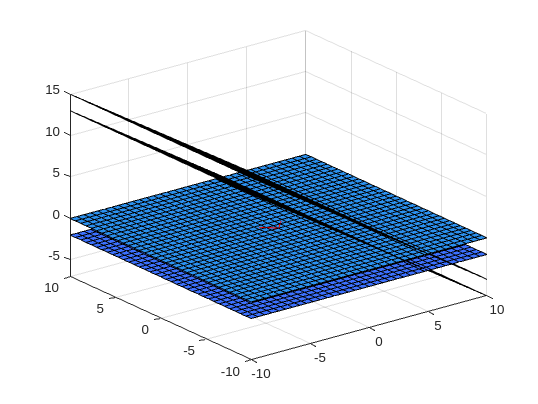

%ans= pi/2 this means they're orthogonal eigenspaces
fsurf(B, [-10, 10]); hold on; axis tight;
quiver3(0,0,0,V1(1),V1(2),V1(3),'Color','red');
quiver3(0,0,0,V2(1),V2(2),V2(3),'Color','red');

## Diagonalization of matrices


A=[1/4 3/4;1 1/2]

A =     0.2500    0.7500
    1.0000    0.5000


P=charpoly(A) %Characteristic polynomial

P =     1.0000   -0.7500   -0.6250


w=roots(P) %eigenvalues 

w =     1.2500
   -0.5000


V1=null(A-w(1)*eye(2)) %eigenvector v1

V1 =     0.6000
    0.8000


V2=null(A-w(2)*eye(2)) %eigenvector v2

V2 =    -0.7071
    0.7071


S=[V1 V2]; %S diagonalizes A
inv(S)*A*S % S\A*S

ans =     1.2500   -0.0000
   -0.0000   -0.5000


[S,d]=eig(A,'vector'); 
inv(S)*A*S % Diagonal matrix

ans =    -0.5000    0.0000
    0.0000    1.2500


A=[5 4;4 5]

A =      5     4
     4     5


A=sym(A)

$$A = \left(\begin{array}{cc} 5 & 4\\ 4 & 5 \end{array}\right)$$

P=charpoly(A)

$$P = \left(\begin{array}{ccc} 1 & -10 & 9 \end{array}\right)$$

w=roots(P)

$$w = \left(\begin{array}{c} 1.0\\ 9.0 \end{array}\right)$$

V1=null(A-w(1)*eye(2))

$$V1 = \left(\begin{array}{c} -1.0\\ 1 \end{array}\right)$$

V2=null(A-w(2)*eye(2))

$$V2 = \left(\begin{array}{c} 1.0\\ 1 \end{array}\right)$$

V=[V1,V2];
inv(A)*A*V %%%V diagonalizes A

$$ans = \left(\begin{array}{cc} -1.0 & 1.0\\ 1 & 1 \end{array}\right)$$

V'*A*V

$$ans = \left(\begin{array}{cc} 2.0 & 0\\ 0 & 18.0 \end{array}\right)$$


% Or you can do
O=orth(V)

$$O = \left(\begin{array}{cc} -0.70710678118654752440084436210485 & 0.70710678118654752440084436210485\\ 0.70710678118654752440084436210485 & 0.70710678118654752440084436210485 \end{array}\right)$$

O'*A*O

$$ans = \left(\begin{array}{cc} 1.0 & 0\\ 0 & 9.0 \end{array}\right)$$


% Why twice the eigenvalues?

clf;

Application of diagonalization of matrix 1

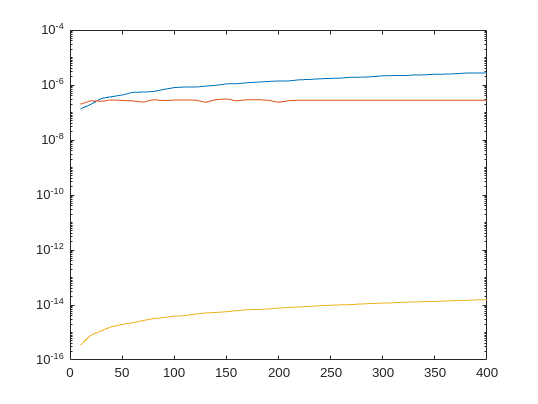

A2=[0.95 0.03;0.05 0.97]; % double precision
A1=single(A2); % single precision
[V2,D2]=eig(A2); [V1,D1]=eig(A1);
nMIN=10; nMAX=400; nSTEP=10; nVals=(nMIN:nSTEP:nMAX)';
E22=zeros(numel(nVals),1); E12diag=zeros(numel(nVals),1); E12pow=zeros(numel(nVals),1);
for k=1:numel(nVals)
	n=nVals(k);
	A2pow=A2^n; % A^n in double prec.
	A1pow=A1^n; % A^n in single prec.
	A2diag=V2*diag(diag(D2).^n)/V2; % *inv(V2)
	A1diag=V1*diag(diag(D1).^n)/V1; % *inv(V1)
	E22(k)=norm(A2pow-A2diag)/norm(A2diag);
	E12pow(k)=norm(A1pow-A2diag)/norm(A2diag);
	E12diag(k)=norm(A1diag-A2diag)/norm(A2diag);
end
figure(1); semilogy(nVals,[E12pow E12diag E22])

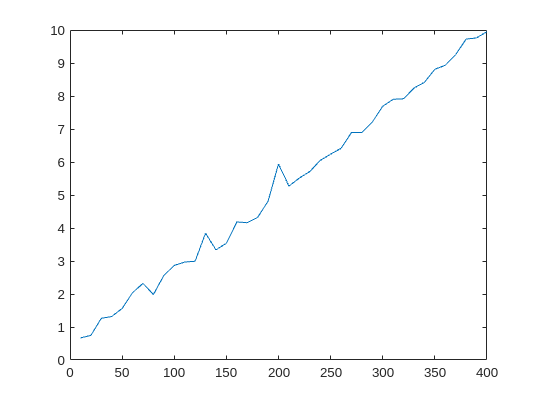

figure(2); plot(nVals,E12pow./E12diag)